# Sessió 9

**Yaiza Cano, Narcís Terrado**

## 1.1. Processat + Segmentació per binarització per Otsu

La imatge amb la que treballarem en aquest primer apartat de la pràctica serà *arros.tif. *Per segmentar-la automàticament per binarització per Otsu, primerament probarem a fer-ho directament convertint la imatge a una imatge binària.

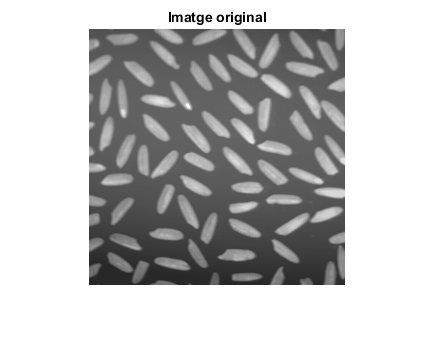

orig = imread("arros.tif");
imshow(orig), title("Imatge original");

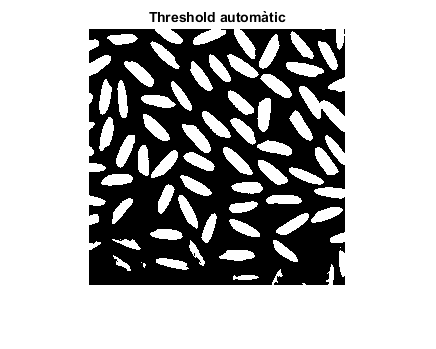


%segmentació per binarització per Otsu
bw = im2bw(orig, graythresh(orig)); 
figure, imshow(bw), title("Threshold automàtic");

Com podem veure, en aquesta binarització perdem grans. Això és degut a que la il·luminació no és gens homogènia i els detectors automàtics de llindar no detecten correctament.

Per arreglar aquest problema, hem de filtrar morfològicament la imatge separant la il·luminació que hi ha de fons per a posteriorment restar-se-la.

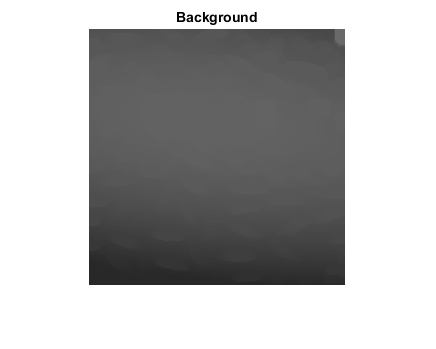

%filtre morfològic
bg = imopen(orig, strel('disk',10));
figure, imshow(bg), title("Background");

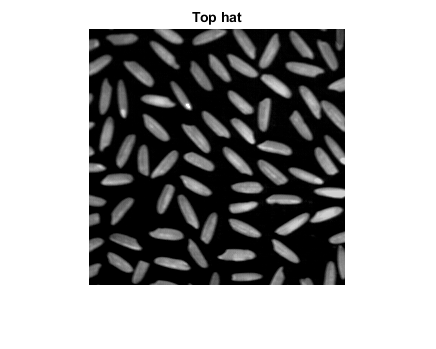


%mostrem el background com si fos una superfície
figure, surf(bg); title("Background com a superfície");

%li restem el background a la imatge.
y = imsubtract(orig, bg);
figure, imshow(y, []), title("Top hat");

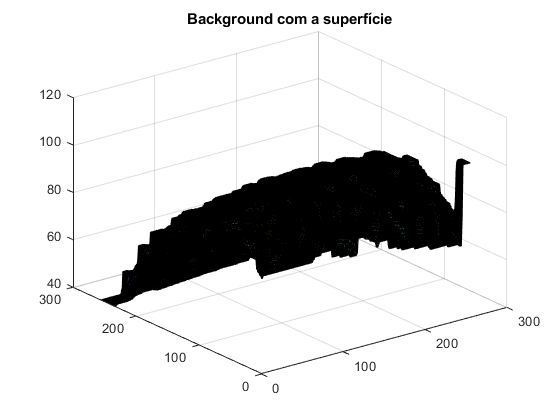

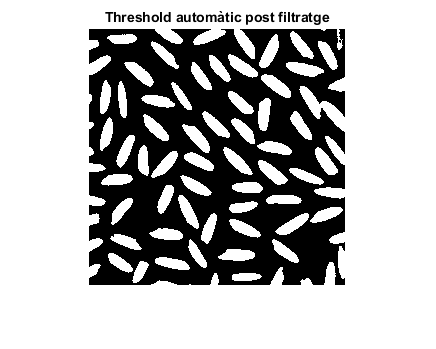


%tornem a segmentar la imatge per Otsu
bw = im2bw(y, graythresh(y));
figure, imshow(bw), title("Threshold automàtic post filtratge");

Ara podem comprobar que amb la resta d'imatges aconseguim una imatge sense il·luminació *Top hat, *on es distingueixen, ara sí, perfectament tots els grans i amb la qual podem obtenir una bona binartizació per Otsu.

## 1.2. Etiquetat + Descripció de regions

Un cop tenim la imatge binaritzada correctament, etiquetem la imatge amb motiu d'obtenim descriptors de les regions els quals computen totes les mesures de forma possibles.

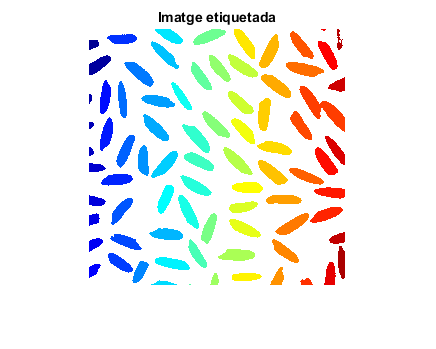

%etiquetem la imatge segmentada
[eti, num] = bwlabel(bw,4);
figure, imshow(label2rgb(eti)), title("Imatge etiquetada");


%comptem ara el nombre d'objectes a la imatge
num;

%obtenim descriptors de les regions
Dades = regionprops(eti,"all");

## 1.3. Exercici

Abans de representar les propietats descrites a *regionprops, *hem de modificar la imatge *bw*, ja que en la que tenim ara apareixen grans d'arròs en contacte que el computador interpreta que són 1 sol i grans que toquen les vores. Tots aquests grans falsegen els resultats i per tant, s'han d'eliminar de la imatge.

#### Separació de grans en contacte amb altres

Per dur a terme aquest exercici, hem seguit el tutorial de *watershed segmentation* d'*Steve Eddins*, link: [https://blogs.mathworks.com/steve/2013/11/19/watershed-transform-question-from-tech-support/.](https://blogs.mathworks.com/steve/2013/11/19/watershed-transform-question-from-tech-support/.)

- Computem la transformació de la *distància*. 

- Computem la transformació per *watershed*.

- Utilitzem les línies blanques obtingudes pel *watershed* (Ld == 0) per segmentar la imatge binària.

- Cobrim els mínims locals creats per la sobresegmentació anterior i modifiquem la transformació de la *distància* per a obtenir els resultats que desitgem.

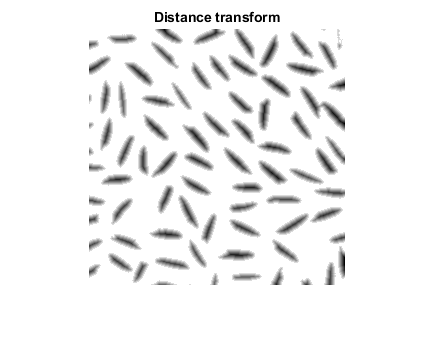

D = -bwdist(~bw);
figure, imshow(D,[]), title("Distance transform");

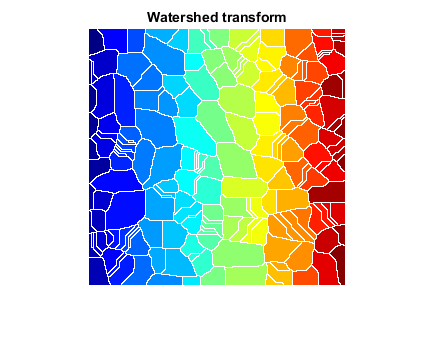


Ld = watershed(D);
figure, imshow(label2rgb(Ld)), title("Watershed transform")

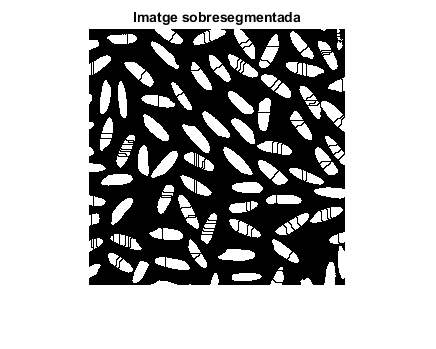


bw2 = bw;
bw2(Ld == 0) = 0;
figure, imshow(bw2), title("Imatge sobresegmentada")

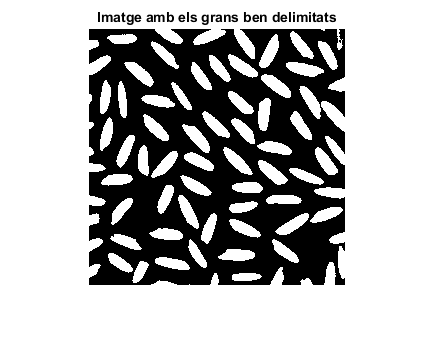


mask = imextendedmin(D,2);
D2 = imimposemin(D,mask);
Ld2 = watershed(D2);
bw3 = bw;
bw3(Ld2 == 0) = 0;
figure, imshow(bw3), title("Imatge amb els grans ben delimitats")

#### Eliminació de grans que toquen les vores

Per dur a terme aquest exercici, hem seguit el procediment de la *dilatació condicionada* explicada a la *sessió 4.*

- Creem una imatge que ens servirà com a *marker *la qual serà tota negra menys un petit marc al voltant que serà blanc.

- Creem un *element estructural *amb el que dilatarem el *marker* que després sobreposarem a la imatge.

- Reconstruirem una imatge amb tots aquells grans d'arròs que estan en contacte amb les vores i que ara tenim identificats.

- Restem la imatge anterior a la original.

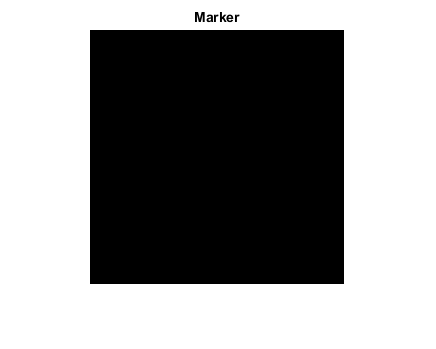

mark = true(256);
mark(2:end-1, 2:end-1) = 0;
figure, imshow(mark), title("Marker");

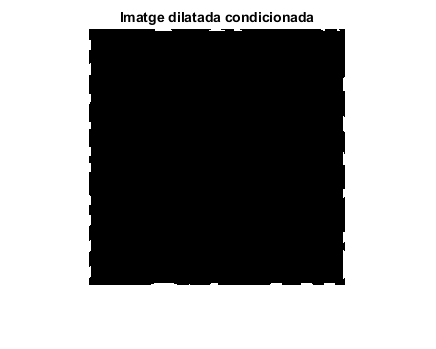


ee = strel('disk',1);
dilc = imdilate(mark,ee) & bw3;
figure, imshow(dilc), title("Imatge dilatada condicionada");

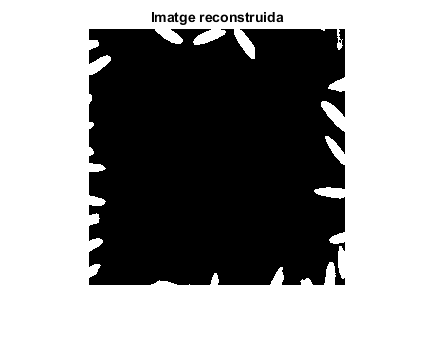


rec = imreconstruct(mark, bw3);
figure, imshow(rec); title("Imatge reconstruida");

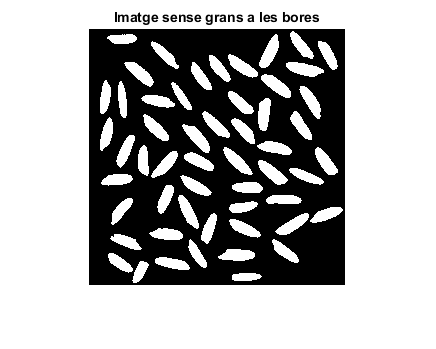


sub = imsubtract(bw3,rec);
figure, imshow(sub,[]), title("Imatge sense grans a les bores")

#### Obtenció i representació de propietats

Un cop etiquetada la imatge, queda decidir quines propietats són les que volem representar per definir la qualitat dels grans d'arròs.

Nosaltres hem escollit: 

- Circularity.

- Eccentricity.

- Relació entre axis.

- Relació entre diàmetre de Feret.

A més a més, hem numerat els grans d'arròs per a poder interpretar degudament els resultats representats als plots.

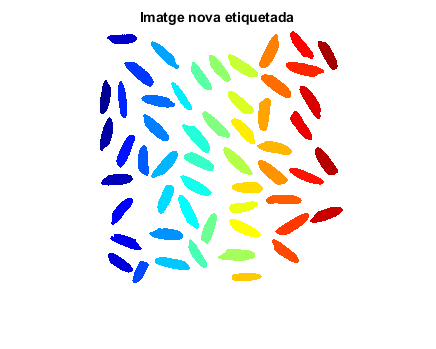

[eti, num] = bwlabel(sub,4);
figure, imshow(label2rgb(eti)), title("Imatge nova etiquetada");

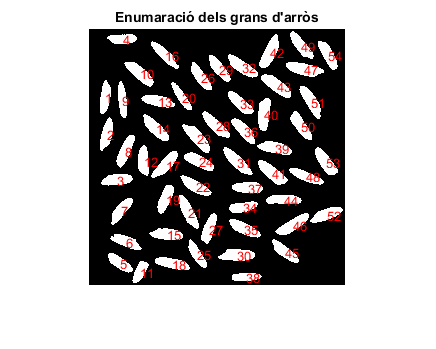


Dades = regionprops(eti,"all");

% NUMERACIÓ DELS GRANS D'ARRÒS
s = regionprops(eti,"Centroid");
figure, imshow(sub), title("Enumaració dels grans d'arròs")
hold on
    for k = 1 : num
        text(s(k).Centroid(1), s(k).Centroid(2), sprintf('%d', k), 'color', 'r')
    end
hold off

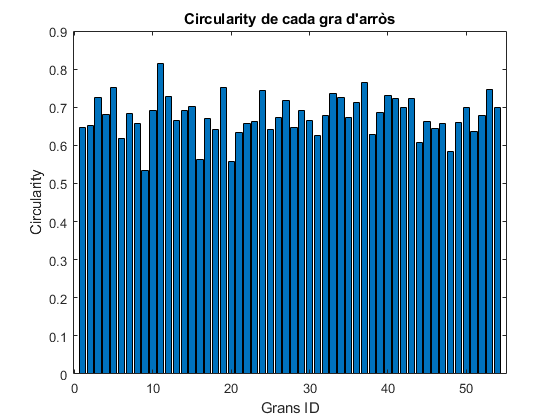


% CIRCULARITY 
figure,
bar(1:num,[Dades.Circularity]);
title("Circularity de cada gra d'arròs");
ylabel("Circularity");
xlabel("Grans ID");

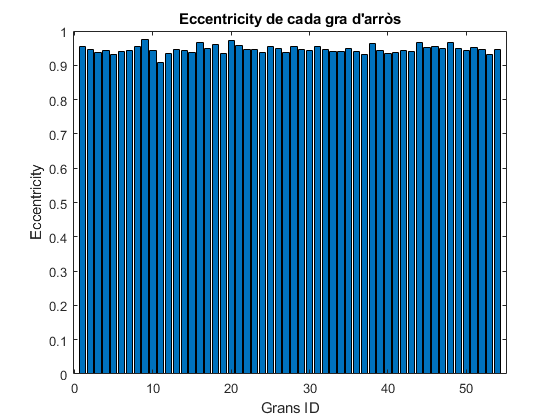


% ECCENTRICITY
figure,
bar(1:num,[Dades.Eccentricity]);
title("Eccentricity de cada gra d'arròs");
ylabel("Eccentricity");
xlabel("Grans ID");

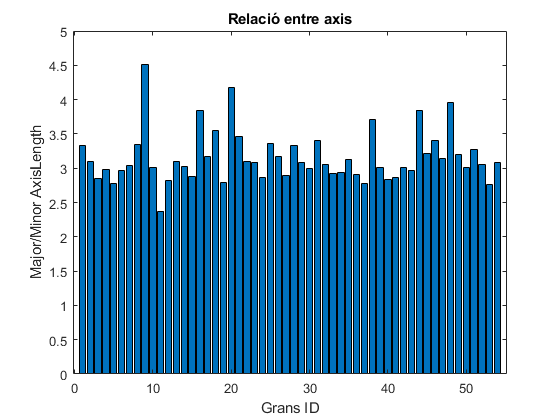


% RELACIÓ MAJOR AXIS I MINOR AXIS
axis = regionprops(eti, "MajoraxisLength", "MinoraxisLength");
a = [];
for k = 1 : num
    a(k) = axis(k).MajorAxisLength / axis(k).MinorAxisLength;
end
figure
bar(1:num, [a]); title("Relació entre axis");
ylabel("Major/Minor AxisLength");
xlabel("Grans ID");

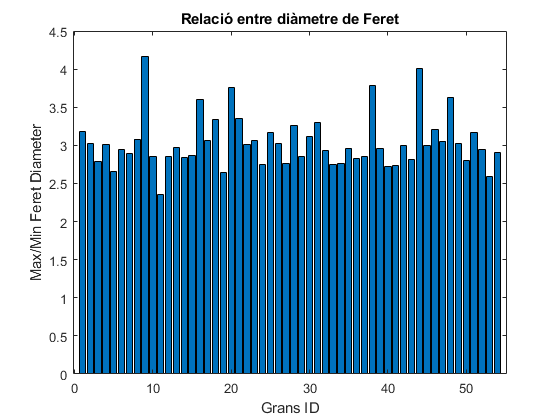



% RELACIÓ MAX FERET DIAMETER I MIN FERET DIAMETER
feret = regionprops(eti, "MaxFeretProperties", "MinFeretProperties");
a = [];
for k = 1 : num
    a(k) = feret(k).MaxFeretDiameter / feret(k).MinFeretDiameter;
end
figure
bar(1:num, [a]); title("Relació entre diàmetre de Feret");
ylabel("Max/Min Feret Diameter");
xlabel("Grans ID");

## 2. Codis de cadena

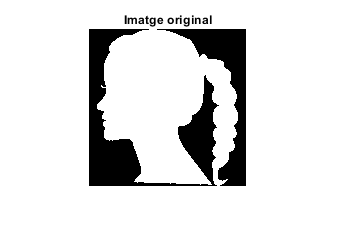

im = imread('head.png');
im = imresize(im,1/4);
imshow(im), title("Imatge original");

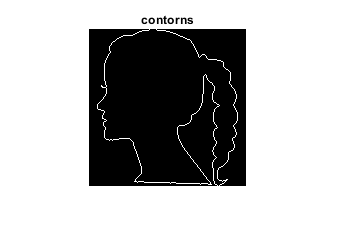


%obtenim el contorn
ero = imerode(im, strel('disk',1));
cont = xor(ero,im);
figure, imshow(cont), title("contorns");

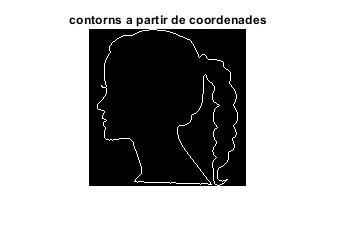


%obtenim les coordenades del contorn
[fila, col] = find(im, 1); %busquem el primer píxel
B = bwtraceboundary(im, [fila, col], 'E'); %direcció est a l'atzar
%B conté les coordenades

%Ho comprovem mostrant el resultat
aux = zeros(size(im));
aux(sub2ind(size(aux),B(:,1),B(:,2))) = 1;
figure, imshow(aux), title("contorns a partir de coordenades")

## 2.1. Exercici

Trobar els codis de cadena incrementals a partir de B.

[rows, ~] = size(B);
chain = zeros(1,rows);
startingDir = absoluteDir(B(2,:) - B(1,:));
lastDir = startingDir;

for row = 2:rows
    nextDir = absoluteDir(B(row,:) - B(row-1,:));
    dir = nextDir-lastDir;
    if dir < 0
    dir = dir + 8;
    end
    chain(row-1) = dir;
    lastDir = nextDir;
end
dir = nextDir-lastDir;
if dir < 0
    dir = dir + 8;
end
chain(rows) = dir;
chain

chain =      0     0     0     0     0     0     1     7     0     1     7     1     0     0     0     0     1     4     0     0     4     7     5     0     1     0     1     1     1     7     0     0     1     7     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


## 3. Descriptors de Fourier

Els descriptors de *Fourier* són invariants tant a transformacions geomètriques i tolerants davant del soroll.

Poden representar un contorn tancat arbitrari amb l'avantatge que, en la majoria de casos, s'obtindrà una bona descripció amb poca quantitat de descriptors.

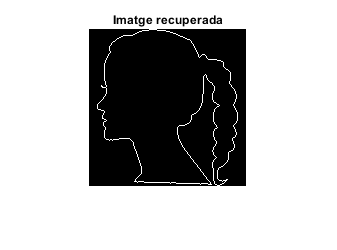

%centrem coordenades
mig = mean(B);
B(:,1) = B(:,1) - mig(1);
B(:,2) = B(:,2) - mig(2);

%convertim les coordenades a complexes
s = B(:,1) + 1i*B(:,2);

%cal que la dimensió del vector sigui parell
[mida, bobo]=size(B);
if(mida/2~=round(mida/2))
    s(end+1,:)=s(end,:); %dupliquem l'ultim
    mida=mida+1;
end
%calculem la Fast Fourier Transform
z = fft(s);
%representem l'espectre
% ho displaiem logaritmic perquè sinó no es veu res
figure, plot(log(abs(z))), title("Descriptors de Fourier");

%Recuperem la imatge original per comprovar que el procès és reversible
ss = ifft(z); %Transformada de Fourier inversa
files = round(real(ss) + mig(1));
cols = round(imag(ss) + mig(2));
aux(:,:)=0;
aux(sub2ind(size(aux),files,cols))=1;
figure,imshow(aux), title('Imatge recuperada')

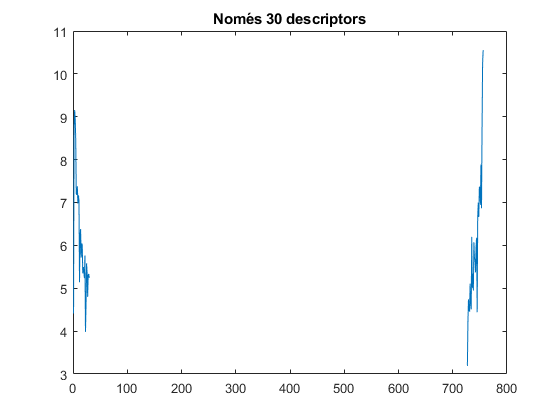


%Reduim la quantitat de descriptors de Fourier
ndesc = 30; %agafem N descriptors
tmp = z;
tmp(ndesc+1:end-ndesc) = 0; %eliminem els del mig perquè es duplica l'espectre
figure, plot(log(abs(tmp))), title("Només 30 descriptors");

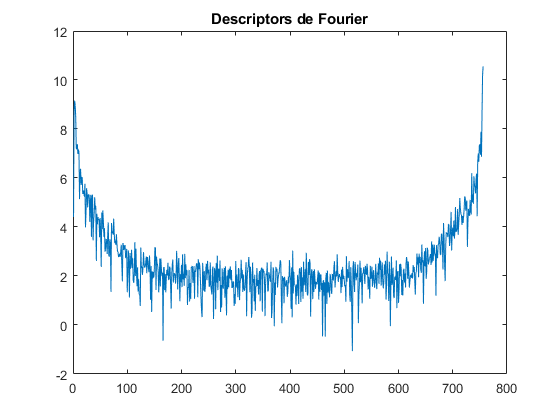

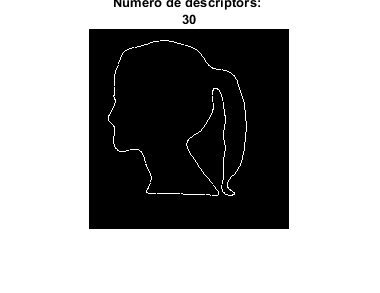


%Tornem al pla imatge a partir de l'espectre modificat
ss2 = ifft(tmp);
%Les coordenades resultants poden sortir del rang de la imatge original
%Creo una imatge més gran per a que les coordenades no se'm surtin de mare
mida = 200;
files = round(real(ss2) + mida/2);
cols = round(imag(ss2) + mida/2);
aux = logical(zeros(mida));
aux(sub2ind(size(aux), files, cols)) = 1;
figure, imshow(aux); title(["Número de descriptors: ", num2str(ndesc)]);

## 3.1. Exercici

Repetim el procediment descrit en l'apartat anterior però utilitzant quantitats de descriptors diferents per veure quin efecte té això en el detall de la imatge obtinguda.

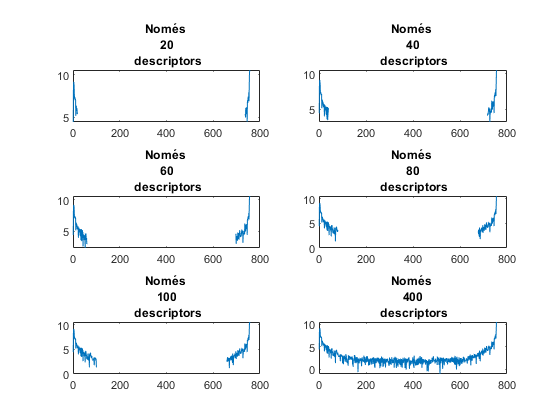

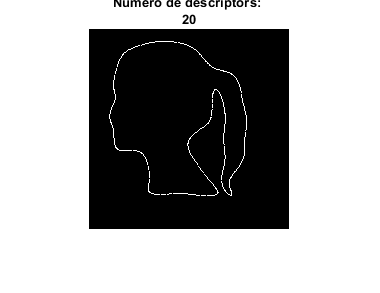

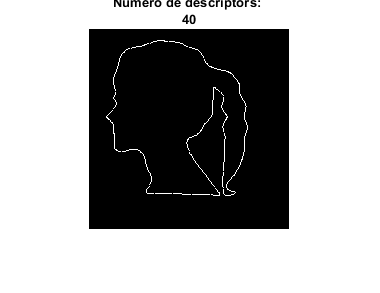

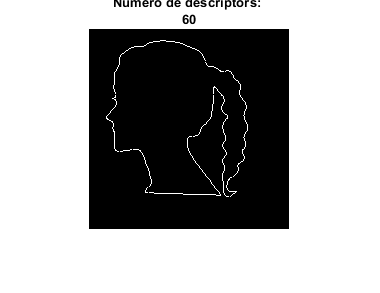

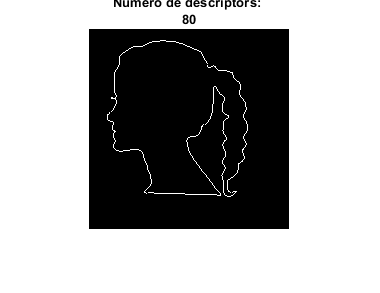

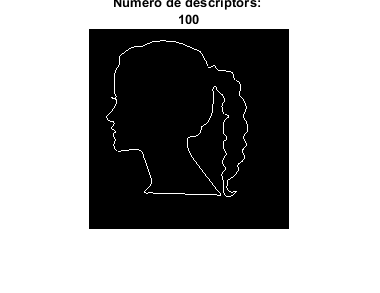

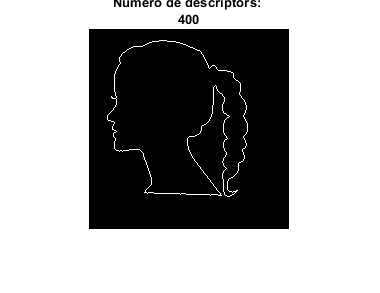

ndesc = [20,40,60,80,100,400];
[fn, cn] = size(ndesc);

tmp = [];
figure,
for k = 1 : cn
    tmp(:, k) = z;
    tmp(ndesc(k)+1:end-ndesc(k),k) = 0;
    subplot(3,2,(k)); plot(log(abs(tmp(:,k)))), title(["Només ", num2str(ndesc(k)), " descriptors"]);
end

pause(0.1); %comentar aquesta línia abans d'exportar a pdf
for k = 1 : cn
    figure, imshow(numDescriptors(200,ifft(tmp(:,k)))); title(["Número de descriptors: ", num2str(ndesc(k))]);    
end

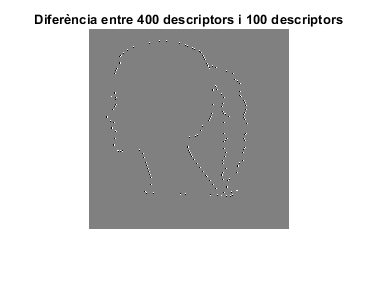

im5 = numDescriptors(200,ifft(tmp(:,5)));
im6 = numDescriptors(200,ifft(tmp(:,6)));
figure, imshow(imsubtract(im6,im5),[]); title("Diferència entre 400 descriptors i 100 descriptors")

Com podem observar, a major número de descriptors de *Fourier*, amb més punts es dibuixaran a la silueta tancada que tenim i, per tant, més nivell de detall obtindrem. En el nostre cas, hem decidit asignar valors petits als descriptors per veure millor la diferència entre els dibuixos. Metre probavem valors, vam veure que a partir de 100 descriptors, la diferència entre siluetes no era distingible pels nostres ulls, igualment hem decidit compara-la amb la de 400 descriptors per a observar la diferència de punts dibuixats.

type numDescriptors.m


function aux = numDescriptors(mida,ss)
files = round(real(ss) + mida/2);
cols = round(imag(ss) + mida/2);
aux = logical(zeros(mida));
aux(sub2ind(size(aux), files, cols)) = 1;
end



type absoluteDir.m


function [dir] = absoluteDir(point)
if point == [0,1]
    dir = 0;
elseif point == [-1,1]
    dir = 1;
elseif point == [-1,0]
    dir = 2;
elseif point == [-1,-1]
    dir = 3;
elseif point == [0,1]
    dir = 4;
elseif point == [1,-1]
    dir = 5;
elseif point == [1,0]
    dir = 6;
else
    dir = 7;
end

